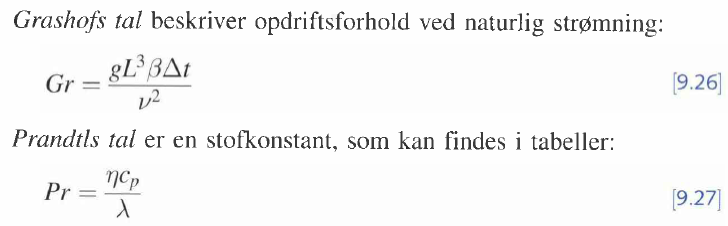

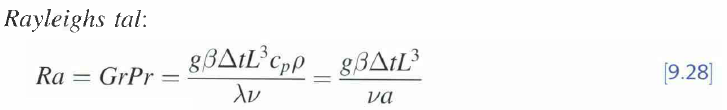

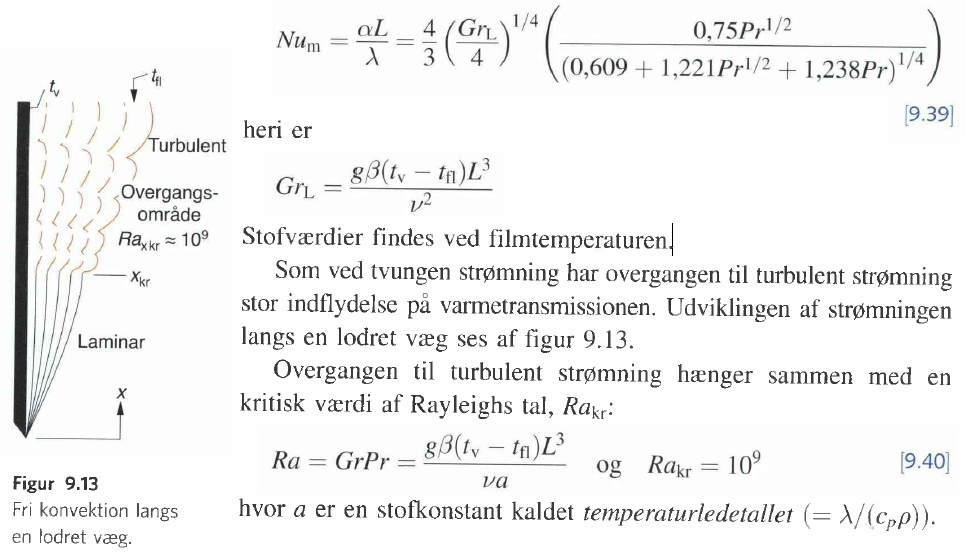

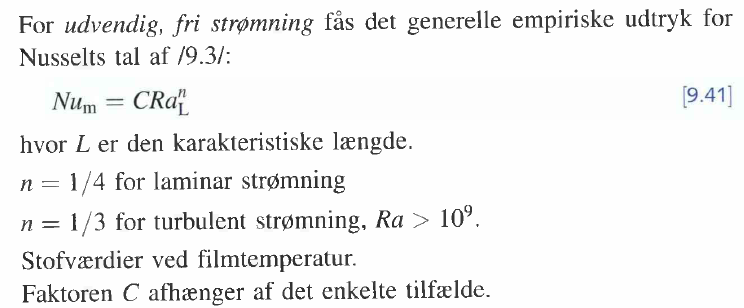

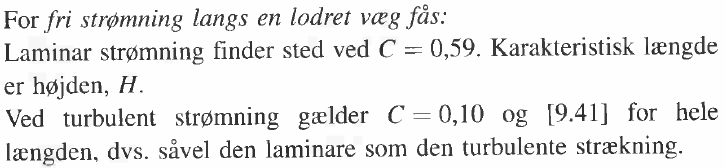

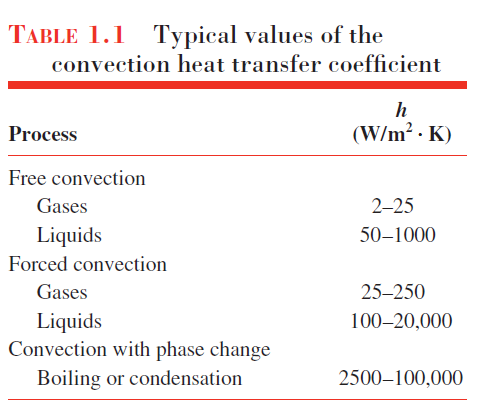


clear all
fluid = 'Air'

fluid = 'Air'

CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5 %surface pressure

T_luft = 20 +273.15;
% T_v = T_luft + 10; % start gæt på væg temperaturen
syms h_luft T_v

g = 9.82;
w_tot = 0.555; %højden af radiatoren
C = 0.59; % til Nussels tal for fri strømning langs en lodret væg
h_start = 10; % start gæt for varmeovergangstallet, W/(m^2*K)

% interation = 10; % antal gange loopet skal køre


T_fluid = (T_luft + T_luft)/2; % middel film temeperatur
mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
rho = CoolProp.PropsSI('D', 'P', P, 'T', T_fluid, fluid); %Densitet
nu = mu/rho;
% nu = 15.06e-6; % ved 20 grad
k_luft = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_fluid, fluid); %thermalConductivity
mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
c_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_fluid, fluid); %specificHeat_p

beta = 1/T_fluid; %volumenudvidelseskoefficienten % [1/K]


Gr = g * beta * (T_v - T_luft)/nu^2;
Pr = mu * c_p / k_luft;

Ra_L = Gr * Pr;
% if Ra_L < 1e9
n = 1/4;
% else
% n = 1/3;
% end

Nu_m = C * Ra_L^n; %== 4/3 * (Gr/4)^(1/4) * g*Pr
h_eq = h_luft == Nu_m/w_tot * k_luft;

T_v = solve(h_eq, T_v)%, ReturnConditions=true)

$$T\_v = \frac{443280521827309275584757098093461393985778545253552871401509610967676335054070480896\,{h_{\mathrm{luft}}}^{4}}{26341446238672091828102460291522907469863219445947649994288097485569199043435498984375}+\frac{5863}{20}$$

vpa(T_v - 273.15, 5)

$$ans = 0.016828\,{h_{\mathrm{luft}}}^{4}+20.0$$



% disp('end loop')
% T_v - 273.15
% h_luft

h = 10 

clear all
h = 10;
g = 9.82;
w_tot = 0.555; %højden af radiatoren
k = 177; %konducteviteten for alu tabel A.1
N = 66; %antal finner per side
w = 0.465; %højden af findenen

L = 0.03; %længden af finnen
T =  0.0005; % tykkelsen af finnen
% h_luft = 10; %convection heat transfer coeffecient = 10  from table 1.1
h_luft = 4.9115; %found in calculation below from a start guess on the film temperature
L_c = L + T/2

L_c = 0.0302

A_f = 2*w*L_c %finne arealet

A_f = 0.0281

A_b = w_tot*1.18 - w*T*N %arealet af basen

A_b = 0.6396

A_t = N*A_f + A_b %total areal finner

A_t = 2.4963

A_c = w*T

A_c = 2.3250e-04

P = 2*w + 2*T

P = 0.9310

m = sqrt(h_luft*P/(k*A_c))

m = 10.5410

A_vand =  w * N/2 * (8e-3 * 3e-3)

A_vand = 3.6828e-04


L = w * N + 4*1.70

L = 37.4900


syms c
c_vand = c;

vand = 'Water';
T_ind = 47 + 273.15

T_ind = 320.1500

T_ud = 28 + 273.15

T_ud = 301.1500

T_vand = (T_ind + T_ud)/2

T_vand = 310.6500

T_vand_s = T_vand

T_vand_s = 310.6500

T_vand_film = (T_vand + T_vand_s)/2

T_vand_film = 310.6500

k_luft = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_vand_film, vand); %thermalConductivity

Unable to resolve the name 'CoolProp.PropsSI'.

eta_vand = CoolProp.PropsSI('V', 'P', P, 'T', T_vand_film, vand);
c_p_vand = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_vand_film, vand);
Pr = eta_vand * c_p_vand / k_luft
% h_vand = 
% R_conv = 1/(h_vand * A_vand)


R_cond = 1/(k*A_vand)

eta_f = tanh(m*L_c) / (m*L_c)
eta_0 = 1 - (N  * A_f) / A_t * (1 - eta_f)
A_t = N*A_f + A_b
R_finner = 1/(eta_0 * h_luft * A_t)


% R_tot = R_conv + R_cond + R_finner



clear all
fluid = 'Air'
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P = 101325; % Pascal eller 1e5 %surface pressure

T_luft = 20 +273.15;
T_v = T_luft + 10; % start gæt på væg temperaturen
syms h_luft

g = 9.82;
w_tot = 0.555; %højden af radiatoren
C = 0.59; % til Nussels tal for fri strømning langs en lodret væg
% h_luft = 10; % start gæt for varmeovergangstallet, W/(m^2*K)

h_plot = [];
T_plot = [];

% Ts = (2:2:20)+273.15;
% Ts = linspace(1,40,40)+273.15
interation = 10; % length(Ts) % antal gange loopet skal køre
for i = 1:interation
    i
    % T_v = Ts(i);
    T_fluid = (T_v + T_luft)/2; % middel film temeperatur
    mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
    rho = CoolProp.PropsSI('D', 'P', P, 'T', T_fluid, fluid); %Densitet
    nu = mu/rho;
    % nu = 15.06e-6; % ved 20 grad
    k_luft = CoolProp.PropsSI('conductivity', 'P', P, 'T', T_fluid, fluid); %thermalConductivity
    mu = CoolProp.PropsSI('viscosity', 'P', P, 'T', T_fluid, fluid); %Dynamisk viscositet
    c_p = CoolProp.PropsSI('Cpmass', 'P', P, 'T', T_fluid, fluid); %specificHeat_p

    beta = 1/T_fluid; %volumenudvidelseskoefficienten % [1/K]

    if rem(i,2) == 0  % statements to execute for even m(i)
        syms T_v
    else
        syms h_luft
    end

    Gr = g * beta * (T_v - T_luft)/nu^2;
    Pr = mu * c_p / k_luft;

    Ra_L = Gr * Pr;
    if rem(i,2) == 1  % statements to execute for even m(i)
        if Ra_L < 1e9
            n = 1/4;
        else
            n = 1/3;
        end
    end


    Nu_m = C * Ra_L^n;
    % Nu_eq = h_luft*L/k_luft = 4/3 * (Gr/4)^(1/4) * g*Pr

    h_eq = 0 == Nu_m/w_tot * k_luft - h_luft;

    if rem(i,2) == 0 % statements to execute for even m(i)
        T_v = solve(h_eq, T_v);
        T_v = double(T_v)
        T_plot(end+1) = T_v;
    else
        h_luft = solve(h_eq, h_luft);
        h_luft = double(h_luft)
        h_plot(end+1) = h_luft;
        
    end
    
end
disp('end loop')
T_v_C = T_v - 273.15
h_luft


plot(linspace(-10,10,length(Ts)), Tx)
yline(min(h_plot))
grid("minor")